Q5 

Steps:

1. Load the Image and Convert to Grayscale:

    First of all, load the input image, and then convert it to grayscale because grayscale images are easier to work with for quantization.

% Load and convert the input image to grayscale
inputImage = imread('https://st4.depositphotos.com/6903990/27898/i/1600/depositphotos_278981062-stock-photo-beautiful-young-woman-clean-fresh.jpg');  % Load the image from file
grayscaleImage = rgb2gray(inputImage);  % Convert the image to grayscale

2. Set the Number of Quantization Levels:

    Decide on the number of grayscale levels for quantization. In this problem, you may set it to 32 levels, which reduces the image detail by allowing fewer shades of gray.

% Quantize the grayscale image to 32 levels
numQuantizationLevels = 32;  % Set the number of quantization levels

3. Scale the Grayscale Image:

    Map pixel values in the grayscaled image from the 0–255 range to a smaller range that would correspond to the types of quantization we want (0–31). We might need to scale up pixel intensity values so they fall within the range of 32 levels

scaledImage = double(grayscaleImage) * (numQuantizationLevels - 1) / 255;  % Scale grayscale values to 0-31

4. Quantize the Image:

    Round the scaled pixel values to the nearest integer within the 0–31 range. This step effectively reduces the number of distinct grayscale levels, as each pixel is assigned one of 32 possible values.

quantizedImage = round(scaledImage);  % Quantize the grayscale values

5. Scale the Quantized Image Back to the Range 0–255:

    Quantize all pixels and then translate them back to original values in the standard grayscale range from 0 to 255. This is because any further processing or display of these images must be done within this range .

quantizedImage = uint8(quantizedImage * 255 / (numQuantizationLevels - 1));  % Scale quantized values back to 0-255

6. Display the Original and Quantized Images:

    Display the original grayscale image and the quantized image side-by-side to see what an effect of the quantization looks like. The quantized image will have fewer shades, so it will look much more reduced and stylized compared with the original.

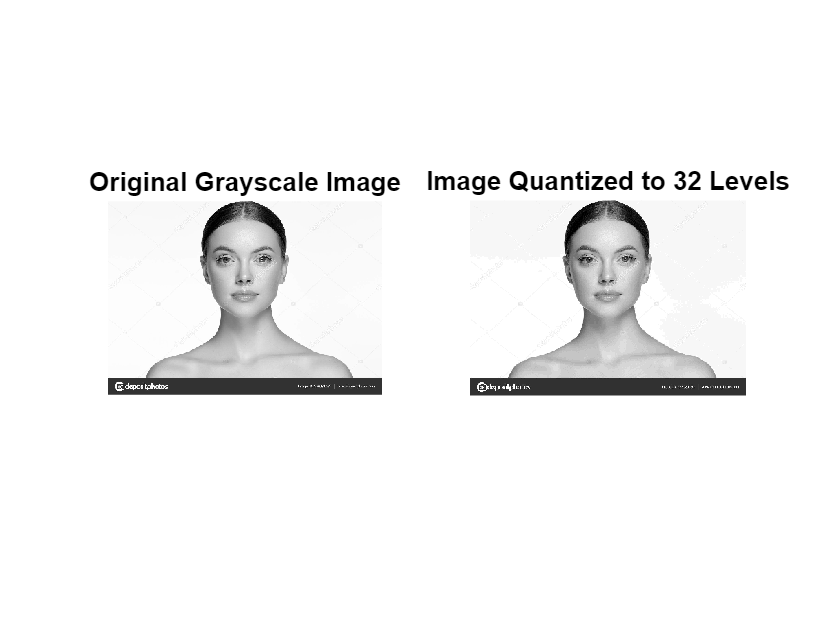

% Display the original and quantized images
figure;
subplot(1, 2, 1); imshow(grayscaleImage); title('Original Grayscale Image');  % Show the original grayscale image
subplot(1, 2, 2); imshow(quantizedImage); title('Image Quantized to 32 Levels');  % Show the quantized image